columns_to_remove = {'work_experience', 'income_from_principal_employer', 'home_ownership_type_id', 'income_other', 'UseOfLoan', 'marital_status_id', 'Gender', 'Debt_to_income_ratio', 'language_code', 'Employment_Duration_Current_Employer_m', 'Age', 'ApplicationType', 'CreditGroup', 'ApplicationDuration'}

columns_to_remove = 1×14 cell array
    {'work_experience'}    {'income_from_principal_employer'}    {'home_ownership_type_id'}    {'income_other'}    {'UseOfLoan'}    {'marital_status_id'}    {'Gender'}    {'Debt_to_income_ratio'}    {'language_code'}    {'Employment_Duration_Current_Employer_m'}    {'Age'}    {'ApplicationType'}    {'CreditGroup'}    {'ApplicationDuration'}


columns_to_keep = setdiff(CRMdataT2.Properties.VariableNames, columns_to_remove);
data = CRMdataT2(:, columns_to_keep)

data = 2232×11 table
    AppliedAmount    LoanDuration    LoanStatus    MaxInterest    MoPaymentDay               PaymentHistory                    education_id        employment_status_id    income_total    nr_of_dependants    occupation_area
    _____________    ____________    __________    ___________    ____________    _____________________________________    ____________________    ____________________    ____________    ________________    _______________

       639.12             12             0             25              10         No previous payments problems            Secondary education        Fully em


sc = creditscorecard(data, BinMissingData=true, ResponseVar="LoanStatus")

sc =   creditscorecard with properties:

                GoodLabel: 0
              ResponseVar: 'LoanStatus'
               WeightsVar: ''
                 VarNames: {'AppliedAmount'  'LoanDuration'  'LoanStatus'  'MaxInterest'  'MoPaymentDay'  'PaymentHistory'  'education_id'  'employment_status_id'  'income_total'  'nr_of_dependants'  'occupation_area'}
        NumericPredictors: {'AppliedAmount'  'LoanDuration'  'MaxInterest'  'MoPaymentDay'  'income_total'  'nr_of_dependants'}
    CategoricalPredictors: {'PaymentHistory'  'education_id'  'employment_status_id'  'occupation_area'}
           BinMissingData: 1
                    IDVar: ''
            PredictorVars: {'AppliedAmount'  'LoanDuration'  'MaxInterest'  'MoPaymentDay'  'PaymentHistory'  'education_id'  'employment_status_id'  'income_total'  'nr_of_dependants'  'occupation_area'}
                     Data: [2232×11 table]


sc = autobinning(sc);
credit_group_bins = {'NumBins',2};
occupation_area_bins = {'NumBins',4}

occupation_area_bins = 1×2 cell array
    {'NumBins'}    {[4]}


language_code_bins = {'NumBins',2}

language_code_bins = 1×2 cell array
    {'NumBins'}    {[2]}


%sc = autobinning(sc,"CreditGroup","Algorithm","EqualFrequency", "AlgorithmOptions",credit_group_bins)
sc = autobinning(sc,"occupation_area","Algorithm","EqualFrequency", "AlgorithmOptions",occupation_area_bins)

sc =   creditscorecard with properties:

                GoodLabel: 0
              ResponseVar: 'LoanStatus'
               WeightsVar: ''
                 VarNames: {'AppliedAmount'  'LoanDuration'  'LoanStatus'  'MaxInterest'  'MoPaymentDay'  'PaymentHistory'  'education_id'  'employment_status_id'  'income_total'  'nr_of_dependants'  'occupation_area'}
        NumericPredictors: {'AppliedAmount'  'LoanDuration'  'MaxInterest'  'MoPaymentDay'  'income_total'  'nr_of_dependants'}
    CategoricalPredictors: {'PaymentHistory'  'education_id'  'employment_status_id'  'occupation_area'}
           BinMissingData: 1
                    IDVar: ''
            PredictorVars: {'AppliedAmount'  'LoanDuration'  'MaxInterest'  'MoPaymentDay'  'PaymentHistory'  'education_id'  'employment_status_id'  'income_total'  'nr_of_dependants'  'occupation_area'}
                     Data: [2232×11 table]


%sc = autobinning(sc,"language_code","Algorithm","EqualFrequency", "AlgorithmOptions",language_code_bins)
%sc = modifybins(sc,'income_from_principal_employer','MinValue',0, 'MaxValue', 13500,'CutPoints',250:500:2500);
%sc = modifybins(sc,'income_other','MinValue',0,'MaxValue', 2900,'CutPoints',50:50:500);
sc = modifybins(sc,'income_total','MinValue',0,'MaxValue', 13500,'CutPoints',500:250:2000);
sc = modifybins(sc,'AppliedAmount','MinValue',0,'MaxValue', 5000,'CutPoints',100:100:700);
sc = modifybins(sc,'MoPaymentDay','MinValue',0,'MaxValue', 30,'CutPoints',2:2:28);
sc = modifybins(sc,'MaxInterest','MinValue',0,'MaxValue', 50,'CutPoints',20:5:45);
sc = modifybins(sc,'LoanDuration','MinValue',0,'MaxValue', 24,'CutPoints',2:2:22);
%sc = modifybins(sc,'ApplicationDuration','MinValue',0,'MaxValue',30,'CutPoints',2:2:16);
sc = modifybins(sc,'nr_of_dependants','MinValue',0,'MaxValue', 10,'CutPoints',1:1:4);
%sc = modifybins(sc,'work_experience','MinValue',0,'MaxValue',120,'CutPoints',4:4:32);
%sc = modifybins(sc,'Employment_Duration_Current_Employer_m','MinValue',0,'MaxValue', 400, 'CutPoints',20:20:180);
%sc = modifybins(sc,'Age','MinValue',0,'MaxValue', 80, 'CutPoints',20:5:60);
%sc = modifybins(sc,'Debt_to_income_ratio','MinValue',0,'MaxValue', 10, 'CutPoints',0.1:0.1:1.4);
Predictor = "AppliedAmount"

Predictor = "AppliedAmount"

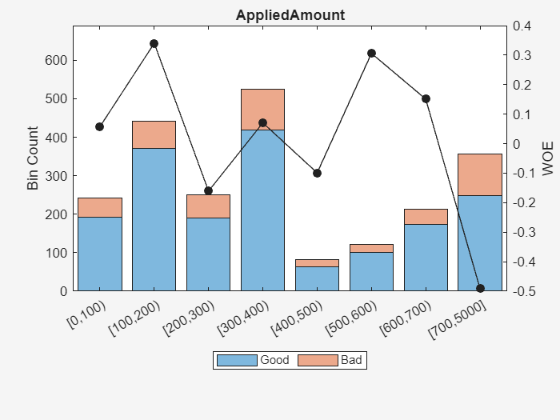

plotbins(sc, Predictor)

[bi,cp] = bininfo(sc,Predictor, 'Statistics',{'woe','InfoValue','odds','Gini'})

bi = 9×7 table
         Bin          Good    Bad       WOE       InfoValue      Odds      Gini  
    ______________    ____    ___    _________    __________    ______    _______

    {'[0,100)'   }     193     49     0.057465    0.00035211    3.9388    0.32296
    {'[100,200)' }     371     71      0.34012      0.020682    5.2254    0.26966
    {'[200,300)' }     190     60     -0.16073     0.0030271    3.1667     0.3648
    {'[300,400)' }     419    105     0.070505     0.0011433    3.9905    0.32046
    {'[400,500)' }      64     19    -0.098961    0.00037455    3.3684    0.35303
    {'[500,600)' }     101     20      0.30598     0.0046313      5.05    0.27594
    {'[600,700)' }     173     40      0.15101     0.0020816     4.325    0.30505
    {'[7

cp =    100
   200
   300
   400
   500
   600
   700





LogOdds = log(bi(:,"Odds"))

LogOdds = 9×1 table
     Odds  
    _______

     1.3709
     1.6535
     1.1527
     1.3839
     1.2144
     1.6194
     1.4644
    0.82208
     1.3134


LogOddsTable = table(bi.Bin, LogOdds.Odds, 'VariableNames', {'Bin', 'LogOdds'})

LogOddsTable = 9×2 table
         Bin          LogOdds
    ______________    _______

    {'[0,100)'   }     1.3709
    {'[100,200)' }     1.6535
    {'[200,300)' }     1.1527
    {'[300,400)' }     1.3839
    {'[400,500)' }     1.2144
    {'[500,600)' }     1.6194
    {'[600,700)' }     1.4644
    {'[700,5000]'}    0.82208
    {'Totals'    }     1.3134



% Initialize an array to store mean values
meanValues = zeros(size(LogOddsTable, 1)-1, 1);

% Iterate through each row of the table
for i = 1:size(LogOddsTable, 1)-1
    % Extract lower and upper bounds from the bin string
    binString = LogOddsTable.Bin{i};
    if startsWith(binString, '[') && endsWith(binString, ')')
        % Format [lower, upper)
        lowerBound = str2double(extractBetween(binString, '[', ','));
        upperBound = str2double(extractBetween(binString, ',', ')'));
    elseif startsWith(binString, '[') && endsWith(binString, ']')
        % Format [lower, upper]
        lowerBound = str2double(extractBetween(binString, '[', ','));
        upperBound = str2double(extractBetween(binString, ',', ']'));
    else
        error('Invalid bin format');
    end
    
    % Calculate mean value within the bin
    meanValues(i) = (upperBound + lowerBound) / 2;
end
NewLogOddsTable = table(meanValues, LogOddsTable.LogOdds(1:end-1,:), 'VariableNames', {'MeanValues', 'LogOdds'});

disp(NewLogOddsTable)

    MeanValues    LogOdds
    __________    _______

         50        1.3709
        150        1.6535
        250        1.1527
        350        1.3839
        450        1.2144
        550        1.6194
        650        1.4644
       2850       0.82208



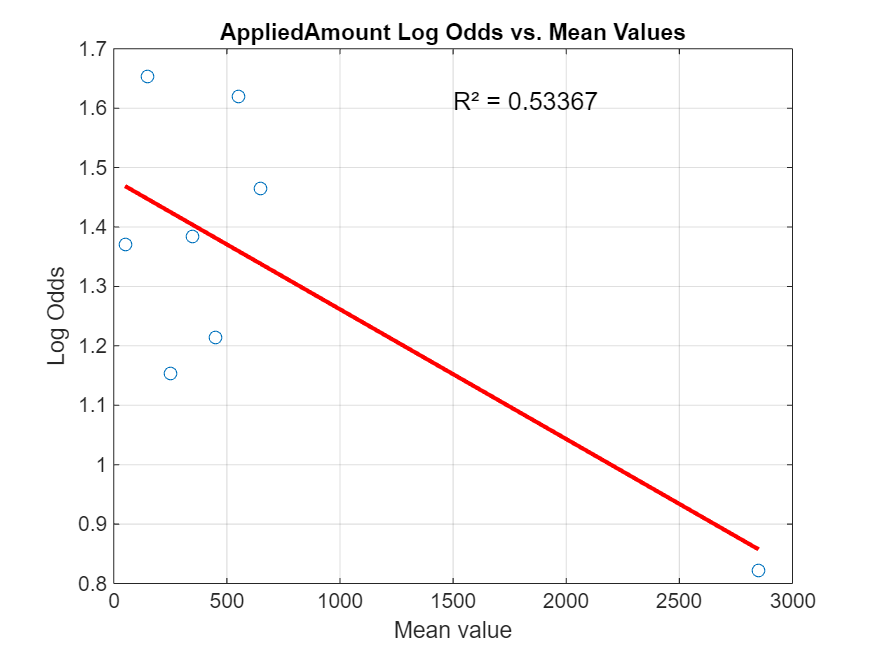

OLSmodel = fitlm(NewLogOddsTable, 'LogOdds ~ MeanValues');
Predictor = strrep(Predictor, '_', ' ');
% Plot
% Plot
figure;
plot(NewLogOddsTable.MeanValues, NewLogOddsTable.LogOdds, 'o');
xlabel('Mean value');
ylabel('Log Odds');
title(Predictor + " "+ 'Log Odds vs. Mean Values');
grid on;
hold on;
plot(NewLogOddsTable.MeanValues, predict(OLSmodel), 'r', 'LineWidth', 2);
r_squared = OLSmodel.Rsquared.Ordinary;
text(0.5, 0.9, ['R² = ' num2str(r_squared)], 'Units', 'normalized', 'FontSize', 12);
legend('off');
hold off;

sc = fitmodel(sc);

1. Adding LoanDuration, Deviance = 2204.3033, Chi2Stat = 101.29127, PValue = 7.9404893e-24
2. Adding MaxInterest, Deviance = 2098.7716, Chi2Stat = 105.53172, PValue = 9.3390947e-25
3. Adding PaymentHistory, Deviance = 2039.4533, Chi2Stat = 59.318318, PValue = 1.3412219e-14
4. Adding occupation_area, Deviance = 2010.0214, Chi2Stat = 29.431823, PValue = 5.7918732e-08
5. Adding employment_status_id, Deviance = 1986.6396, Chi2Stat = 23.381797, PValue = 1.3282958e-06
6. Adding MoPaymentDay, Deviance = 1965.3638, Chi2Stat = 21.275847, PValue = 3.9771125e-06
7. Adding AppliedAmount, Deviance = 1946.0209, Chi2Stat = 19.34291, PValue = 1.0922405e-05
8. Adding nr_of_dependants, Deviance = 1929.1842, Chi2Stat = 16.836733, PValue = 4.0737113e-05
9. Adding income_total, Deviance = 1922.0272, Chi2Stat = 7.1570034, PValue = 0.0074671843

Generalized linear regression model:
    logit(LoanStatus) ~ 1 + AppliedAmount + LoanDuration + MaxInterest + MoPaymentDay + PaymentHistory + employment_status_id + 

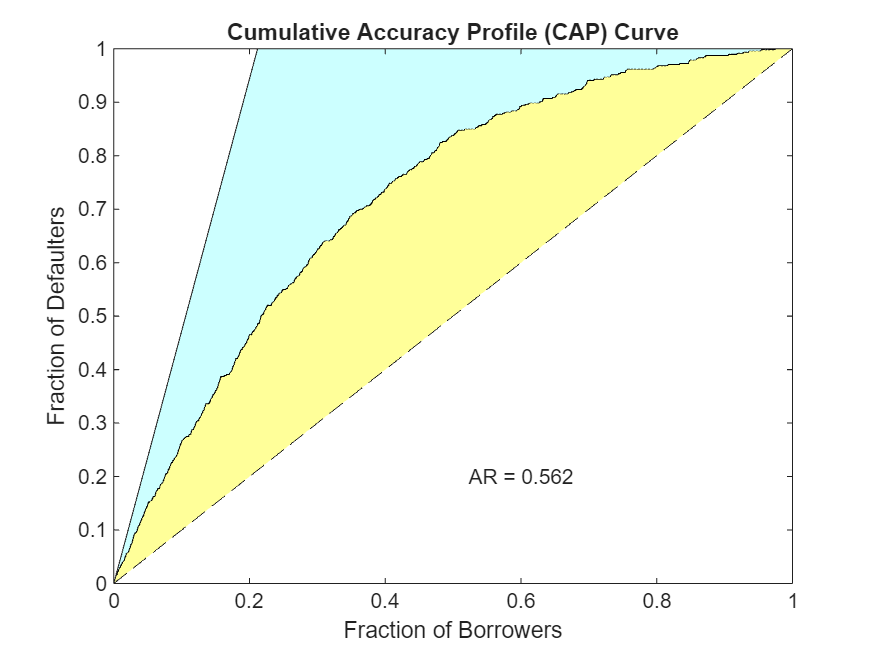

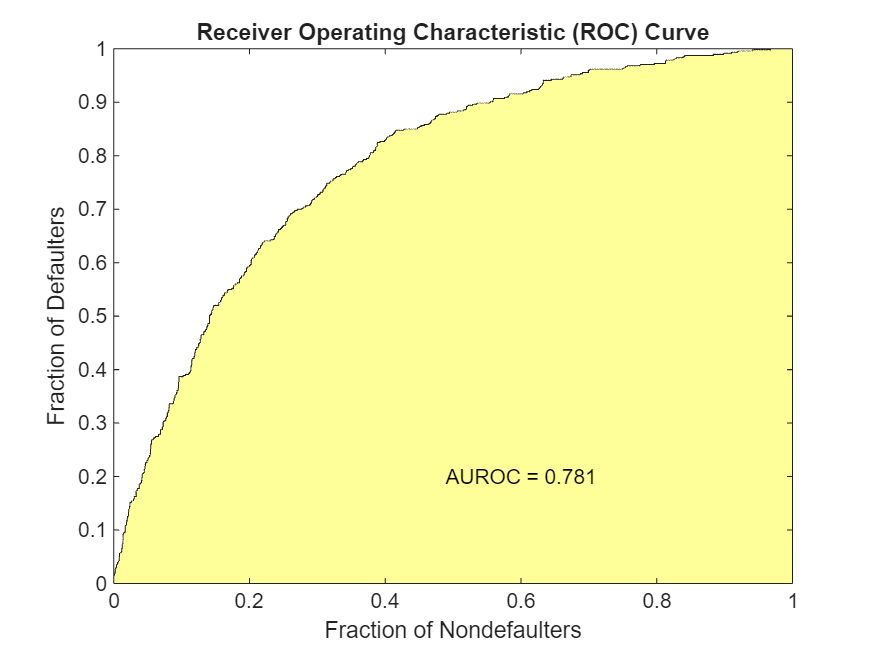

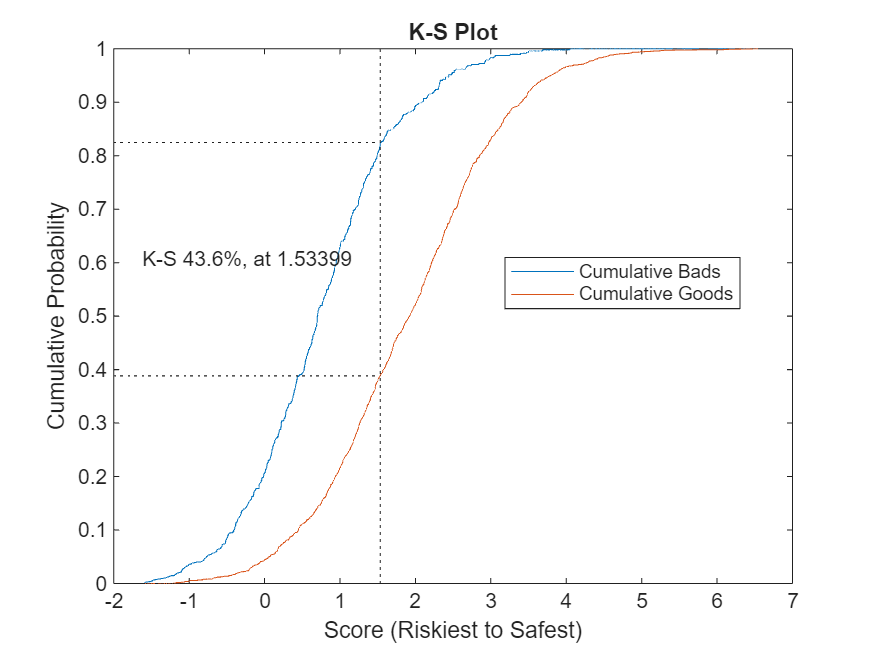

[Stats,T] = validatemodel(sc,'Plot',{'CAP','ROC','KS'});

disp(Stats)

            Measure              Value 
    ________________________    _______

    {'Accuracy Ratio'      }    0.56184
    {'Area under ROC curve'}    0.78092
    {'KS statistic'        }    0.43624
    {'KS score'            }      1.534



pdL = probdefault(sc)

pdL =     0.0872
    0.0252
    0.0049
    0.1110
    0.0713
    0.0167
    0.3232
    0.0111
    0.0331
    0.0138



CategoricalPreds = {'CreditGroup','PaymentHistory','UseOfLoan','ApplicationType','education_id','marital_status_id',...
    'employment_status_id','occupation_area','home_ownership_type_id','language_code','Gender'};
dt = fitctree(CRMdataT2,'LoanStatus ~ CreditGroup+PaymentHistory+AppliedAmount+MaxInterest+LoanDuration+MoPaymentDay+UseOfLoan+ApplicationDuration+ApplicationType+education_id+marital_status_id+nr_of_dependants+employment_status_id+Employment_Duration_Current_Employer_m+work_experience+occupation_area+home_ownership_type_id+income_from_principal_employer+income_other+income_total+language_code+Age+Gender',...
  'MaxNumSplits',50 ,'CategoricalPredictors',CategoricalPreds);
disp(dt)

  ClassificationTree
           PredictorNames: {1×23 cell}
             ResponseName: 'LoanStatus'
    CategoricalPredictors: [1 2 7 9 10 11 13 16 17 21 23]
               ClassNames: [0 1]
           ScoreTransform: 'none'
          NumObservations: 2232


  Properties, Methods



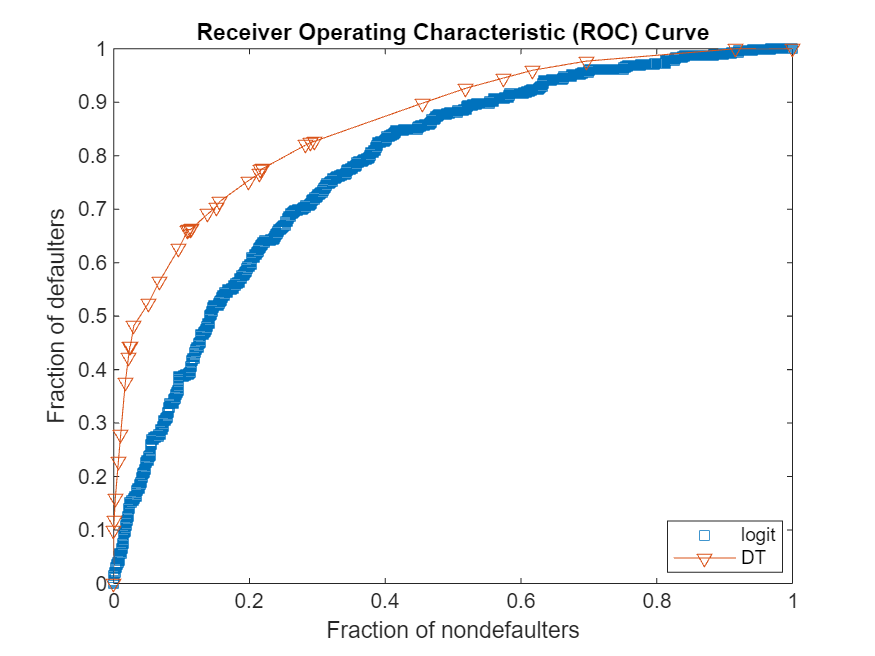

[~,ObservationClassProb,Node] = predict(dt,CRMdataT2);
pdDT = ObservationClassProb(:,2);
[StatsL,tL] = validatemodel(sc);

[x,y,t,AUC] = perfcurve(CRMdataT2.LoanStatus,pdDT,1);
KSValue = max(y - x);
AR = 2 * AUC - 1;

% Create Stats table output
Measure = {'Accuracy Ratio','Area Under ROC Curve','KS Statistic'}';
Value  = [AR;AUC;KSValue];

StatsDT = table(Measure,Value);

figure
plot([0;tL.FalseAlarm],[0;tL.Sensitivity],'s')
hold on
plot(x,y,'-v')
xlabel('Fraction of nondefaulters')
ylabel('Fraction of defaulters')
legend({'logit','DT'},'Location','best')
title('Receiver Operating Characteristic (ROC) Curve')

tValidation = table(Measure,StatsL.Value(1:end-1),StatsDT.Value,'VariableNames',...
    {'Measure','logit','DT'});

disp(tValidation)

            Measure              logit       DT   
    ________________________    _______    _______

    {'Accuracy Ratio'      }    0.56184      0.723
    {'Area Under ROC Curve'}    0.78092     0.8615
    {'KS Statistic'        }    0.43624    0.55825



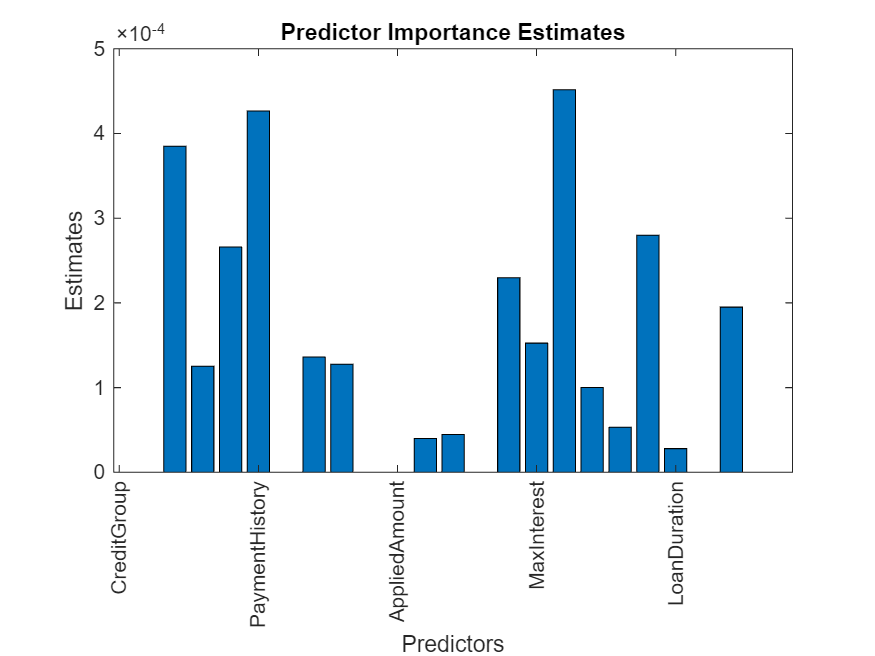

imp = predictorImportance(dt);

figure;
bar(imp);
title('Predictor Importance Estimates');
ylabel('Estimates');
xlabel('Predictors');
h = gca;
h.XTickLabel = dt.PredictorNames;
h.XTickLabelRotation = 90;
h.TickLabelInterpreter = 'none';